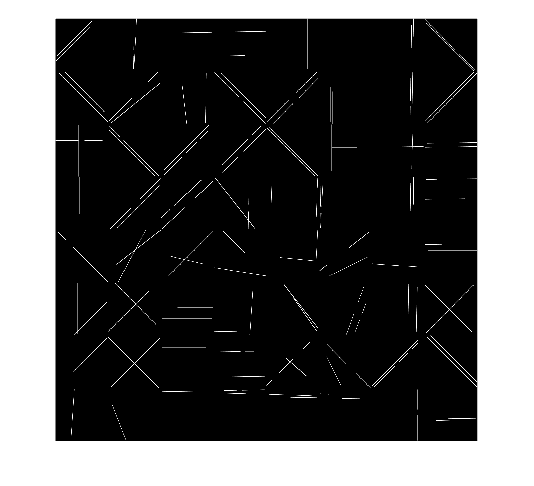

% Load the image
path = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\Development\L88b.jpg";
pathGT = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\GroundTruth\L88bGT.tif";
img = imread(path);
imgGT = imread(pathGT);
% Image dimensions and sub-image size
[rows, cols, ~] = size(img);
subRows = rows / 8; % 256
subCols = cols / 8; % 512

% Initialize a blank (black) image
finalImg = zeros(rows, cols, 'uint8');

% Loop over each part and perform Hough Transform
for i = 1:8 % 8 rows
    for j = 1:8 % 8 columns
        % Extract part of the image
        partImg = img((i-1)*subRows+1:i*subRows, (j-1)*subCols+1:j*subCols, :);

        % Convert to grayscale and detect edges
        grayImg = rgb2gray(partImg);
        edges = edge(grayImg, 'canny');

        % Perform Hough Transform
        [H, theta, rho] = hough(edges);
        peaks = houghpeaks(H, 2);
        lines = houghlines(edges, theta, rho, peaks);

        % Drawing hough lines on the blank image
        for k = 1:length(lines)
            xy = [lines(k).point1; lines(k).point2];
            finalImg = insertShape(finalImg, 'Line', [xy(1,1)+(j-1)*subCols, xy(1,2)+(i-1)*subRows, xy(2,1)+(j-1)*subCols, xy(2,2)+(i-1)*subRows], 'Color', 'white', 'LineWidth', 2);
        end
    end
end

% Display the final image with detected lines on a black background
imshow(finalImg);

disp(size(imgGT));

        2048        2048           3



disp(size(finalImg));

        2048        2048           3



%  if size(finalImg,3) == 3
%     finalImg = rgb2gray(finalImg);
% end
finalImg = im2single(finalImg);
ssimval = ssim(finalImg,single(imgGT))*100;
%displaying the accuracy of resulted image.
fprintf('The SSIM accuracy of the image is %f\n',ssimval)

The SSIM accuracy of the image is 76.585892


fprintf("IOU is %f",findIOUAccuracy(finalImg,imgGT));

IOU is 4.551783

accuracy = calculateAccuracy(finalImg,imgGT);
fprintf('The accuracy score of the image is %f\n',accuracy);

The accuracy score of the image is 88.541389
